## clean up and add path

clear
close all
clc
addpath(genpath('..\..'))%% reach the functions and filters

## path data generation

dt = 0.1;
vx = 1;
vy = 0;

x_c = 0;
y_c = 7;

i = 1;
while x_c <10
    path(i,:) = [x_c, y_c];
    x_c = x_c + vx*dt;
    y_c = y_c + vy*dt + randn*0.1;
    i = i + 1;
end

## model

## ovservation

$y_1$: upward distance measure

$y_2$: downward distance measure

## **states**

$x_1$: height of the drone

$x_2$: displacement of roof, upward

$x_3$: displacement of terrain, downward

## Transition function definition

for all the following functions:

input:

    x: N*Dx: N state vectors, Dx=3

output:

    x: same as input

rnd_terran = {}; % floor model
rnd_roof = {}; % floor model
H = 10; % height of roof

## keep the same


$$x_2 = x_2\\
x_3 = x_3$$


I = 1; % model counter
rnd_terran{I} = @(x_) x_; 
rnd_roof{I} = @(x_) x_; 

## random walk


$$x_{2,3} = x_{2,3} + \epsilon_2$$


I = I + 1;
sig = 0.1;
rnd_terran{I} = @(x_) x_ + sig*randn(size(x_)); 
rnd_roof{I} = @(x_) x_ + sig*randn(size(x_)); 

## no obstical at all


$$x_{2} = H\\
x_{3} = 0$$


I = I + 1;
rnd_terran{I} = @(x_) zeros(size(x_)); 
rnd_roof{I} = @(x_) H*ones(size(x_)); 

## Gaussian obsticles


$$x_{2,3} = C + \epsilon,  \epsilon \sim \mathcal{N}$$


I = I + 1;
sig = 1;
rnd_terran{I} = @(x_) sig*randn(size(x_)); 
rnd_roof{I} = @(x_) H + sig*randn(size(x_)); 

## Exp obsticles 


$$x_2 = H - \epsilon,\ \epsilon\sim Ex(\mu_2)\\
x_3 = \epsilon,\ \epsilon\sim Ex(\mu_3)$$


I = I + 1;
mu = 1;
rnd_terran{I} = @(x_) exprnd(mu, size(x_)); 
rnd_roof{I} = @(x_) H - exprnd(mu, size(x_)); 

## Uniform obsticales


$$x_2 \sim \mathcal{U}(r2)\\
x_3 \sim \mathcal{U}(r3)$$


I = I + 1;
rangeup = H + [1,-5];
rangedown = [-1,5];
rnd_terran{I} = @(x_) ( rand(size(x_)) * range(rangedown) + min(rangedown));
rnd_roof{I} = @(x_) ( rand(size(x_)) * range(rangeup) + min(rangeup));

## Drone movement model


$$x_{1} = x_1 + \epsilon,  \epsilon \sim \mathcal{N}$$


sig = 0.2;
rnd_drone = @(x_) x_ + sig*randn(size(x_));

## Combination of models

RndTrs = {};
modeln = 0;
for it = 1 : I
    for ir = 1 : I
        modeln = modeln + 1;
        RndTrs{modeln} = @(x) [rnd_drone(x(:,1)), ...
                         rnd_roof{ir}(x(:,2)), ...
                         rnd_terran{it}(x(:,3))];
    end
end

## observation model


$$y_1 = x_2 - x_1+\epsilon_1,\ 
\epsilon_1 \sim \mathcal{N}(0,\sigma_1^2)$$



$$y_2 = x_1 - x_3 +\epsilon_2,\ 
\epsilon_2 \sim \mathcal{N}(0,\sigma_1^2)$$


## Filtering reading sensor

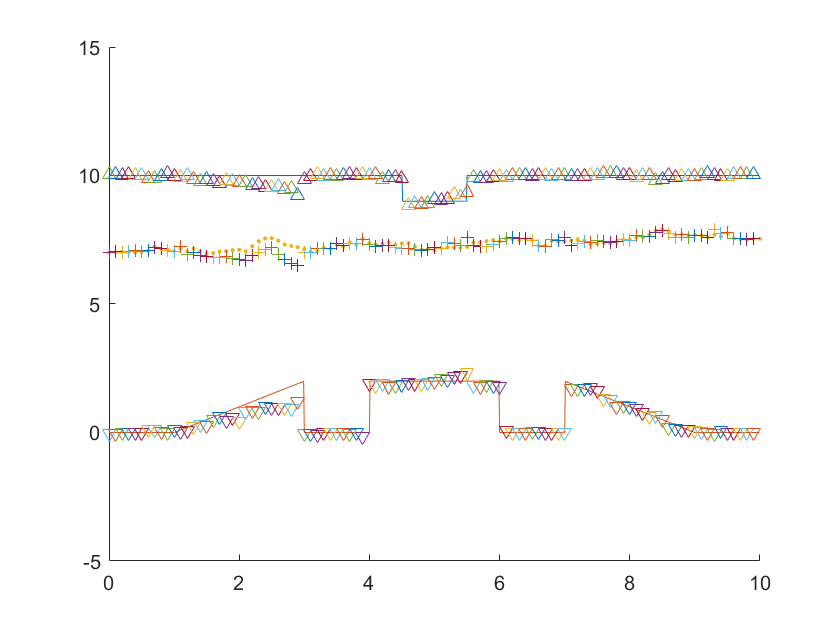

% define the environment
s = sensors(@roof,@terran,path);
% define the filter
M = 100; % number of particles
x0 = [ones([M,1])*7,ones([M,1])*10,ones([M,1])*0]; % initial states
filter = PfBsMM(x0,RndTrs,@LiOb);
% filtering loop

figure
s.plot()
hold on

i = 1;
while s.hasNext()
    [d, x_c] = s.read();
    y = [d.infraredup, d.infrareddown];
    x_hat = filter.estimate(y); % doing filtering
    plot(x_c, x_hat(1),'+')
    plot(x_c, x_hat(2),'^')
    plot(x_c, x_hat(3),'v')
    ylim([-5,15])
    
    m_ind = 1:modeln;
    model_choice(i, 1) = x_c;
    model_choice(i, 2) = m_ind(filter.MW==max(filter.MW));
    i = i + 1;
end

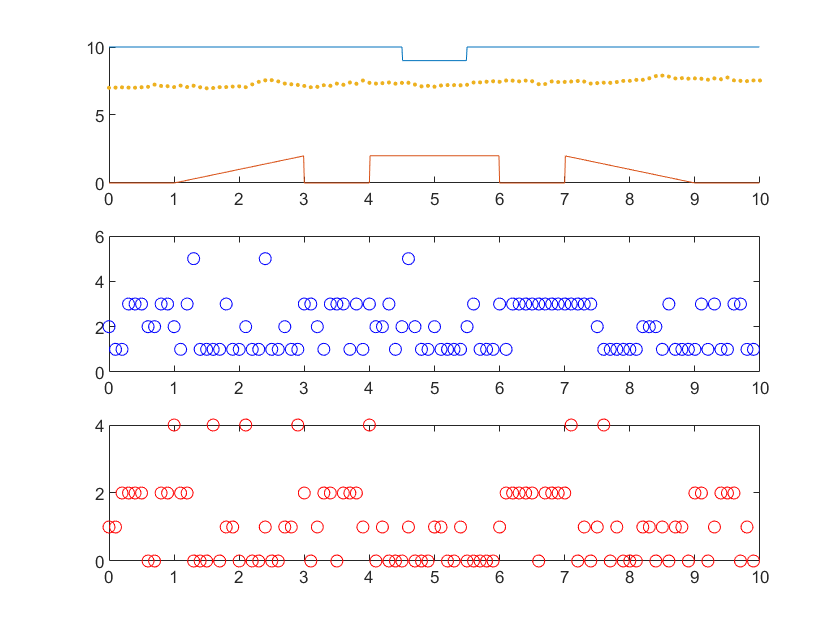

for i = 1 : size(model_choice, 1)
    ir_choice(i) = mod(model_choice(i, 2), I);
    it_choice(i) = floor(model_choice(i, 2)/I);
end
figure
subplot(3,1,1)
s.plot()
subplot(3,1,2)
plot(model_choice(:,1), ir_choice, 'bo')
subplot(3,1,3)
plot(model_choice(:,1), it_choice, 'ro')

# discussions

The observation model is very obvious, and there is not much to talk about it.

There are 2 kinds of state transitions models:

- self coordinated, focus on the change of the states

- world coordinated, focus on the absolute value of the states

While we are estimating 3 states with only the differences are observed. It is impossible to remove the accumulated error with the 1st kind of transition alone. However, utilizing the history states can give a better estimation. The best result is achieved by combining the two kinds.

# Model functions

## room description function

function y = roof(x)
y = 10*ones(size(x));
y(x>4.5 & x<5.5) = 9;
end
function y = terran(x)
y = zeros(size(x));
y(x>1 & x<3) = (x(x>1 & x<3)-1);
y(x>4 & x<6) = 2;
y(x>7 & x<9) = -(x(x>7 & x<9)-9);
end

## observarion likelihood function

input:

y: 1*Dy: one observation, Dy=2

x: N*Dx: N state vectors, Dx=3

output:

p: N*1: likelihood vector

function p = LiOb(y,x)
% observation likelihood

% parameter
H = 10; % known
sig1 = 0.1;
sig2 = 0.1;
% passing
N = size(x, 1);
% calculate the likelihood saperately
p1 = normpdf(x(:,2) - x(:,1), y(1), sig1);
p2 = normpdf(x(:,1) - x(:,3), y(2), sig2);
p = p1 .* p2;
end